# Graph PRO

## First example

clc;
clear;
s = [1 2 2 3 ];
t = [2 3 4 4 ];
w = [1 2 4 2 ];

Gr = Graph_pro(s,t, w);
Gr = Gr.setUndirected(1);
Gr.floyd_warshall()

ans =      0     1     3     4
   Inf     0     2     3
   Inf   Inf     0     1
   Inf   Inf   Inf     0


## Second Example

s = [10 20 20 30 ];
t = [20 30 20 40 ];

Gr = Graph_pro(s,t);
Gr = Gr.setUndirected(0);

Gr.dijkstra()

ans =      0     1     2     3
     1     0     1     2
     2     1     0     1
     3     2     1     0


Gr.floyd_warshall()

ans =      0     1     2     3
     1     1     1     2
     2     1     0     1
     3     2     1     0


## From File

clear;

Gr = Graph_pro();
Gr = Gr.readData("data/facebook_combined.txt");
Gr = Gr.setUndirected(1);

Gr.floyd_warshall();

## Creating a random Graph

clear;
Gr = Graph_pro();
Gr = Gr.creategraph(5,0.75,[1])

Gr =   Graph_pro with properties:

        source: [1 1 1 1 2 2 3 3 4]
        target: [2 3 4 5 4 5 4 5 5]
        weight: [1 1 1 1 1 1 1 1 1]
        vertex: [1 2 3 4 5]
    undirected: 0


Gr.floyd_warshall()

ans =      0     1     1     1     1
     1     0     2     1     1
     1     2     0     1     1
     1     1     1     0     1
     1     1     1     1     0


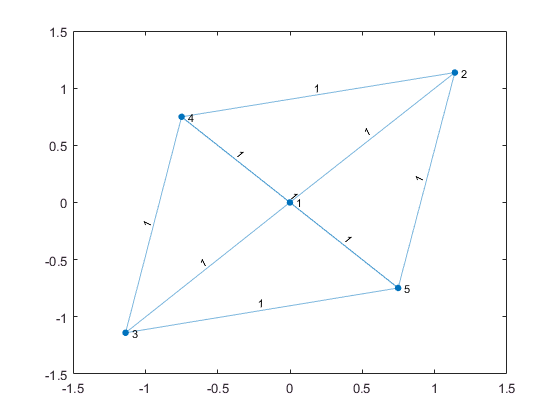

% Plot graph with other module
G = graph(Gr.source,Gr.target, Gr.weight);
p = plot(G);
labeledge(p,1:numedges(G),Gr.weight);

## Test Dijkstra & Floy-Warshall aleatorio entre nodes

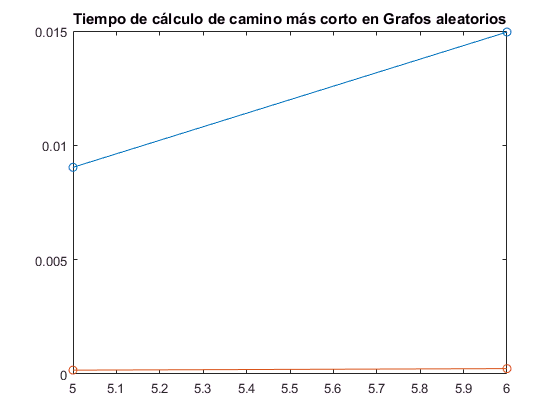

minNodes = 5;
maxNodes = 6;
repeticiones = 1000;

Gr = Graph_pro();
promediosDijkstra = Gr.test_calc("dijkstra", minNodes, maxNodes, repeticiones);
promediosFloyd = Gr.test_calc("floyd_warshall", minNodes, maxNodes, repeticiones);

numNodes = minNodes:maxNodes;
plot(numNodes,promediosDijkstra, '-o');
hold on;
plot(numNodes,promediosFloyd, '-o');
hold off;
title('Tiempo de cálculo de camino más corto en Grafos aleatorios');

ylabel('Tiempo (seconds)');

Undefined function or variable 'ax1'.

legend(['Dijkstra'],['Floyd-Warshall']);
for k=1:numel(numNodes)
      text(numNodes(k),promediosDijkstra(k),['(' num2str(numNodes(k)) ',' num2str(promediosDijkstra(k)) ')'])
      text(numNodes(k),promediosFloyd(k),['(' num2str(numNodes(k)) ',' num2str(promediosFloyd(k)) ')'])
end

